%% Idea : Rather than simultaneous optimization of all three gears, there is a 
% very small search space when using cut/hobbed gears due to the limited
% number of cutters available and the sun gear size is desired to be as small as possible
% for the sake of torque density and limited life. This assumption breaks down when EDM gears
% are used as an infinite number of modules are available. This calculator
% is still applicable to EDM gears, but use the defined module range
% instead of fixed module array instead to account for a large range of
% gear possibilities.


## Script Overview

Before using this script, these parameters MUST be defined in the setting sheet

- Motor shaft diameter

- If using max size setting for center distance:

-     Wheel Bearing Inner Diameter

-     Planet

- Define optimization targets and constraints

- Define module sweep range

- Calculates range of possible sun gear solutions based on applied constraints

- Calculates possible planet gear sun stages based on applied constraints. Calculates planet shaft center distance

- Calculates possible ring gear mesh based on previously defined center distance.

## Gearbox Targets

bending_safety_target = 1.2; % target safety factor that will be used to filter results from the sizing module
wear_safety_target = 1.1; % target safety factor that will be used to filter results from the sizing module
target_gr = 10;    % target gear ratio that will be used to filter results from the sizing module
gb_rad_lim = 64;   % maximum radial size the planetary assembly can have
planetbearingOD = 16; % OD of the planet gear bearing (sets the minimum pitch diameter of the planet)
if true % Use manual center distance option or maximum possible size for the given bearing and 
    target_center_dist = 38.1; 
else
    target_center_dist = 1000*(wheelbearing.internalDiameter - planetPin.diameter)/2; %#ok<*UNRCH> 
    fprintf("Target Center Distance (mm): %.2f",target_center_dist);
end
makeIdenticalPlanets = true;

(There are configurations of gears where the planet gears are not interchangeable in which the ring stage to sun stage angular alignment needs to be different for each gear, check this box to enforce interchangeable

planets as an optimization constraint. This reduces the number of valid solutions but reduces cost and assembly difficulty.)

Definitions:

- Bending Safety Target - target bending safety factor that will be used to filter results from the sizing module

- Wear Safety Target - target wear safety factor that will be used to filter results from the sizing module;

- Target Gear Ratio - target gear ratio that will be used to filter results from the sizing module

- Maximum radial size - the radius of a theoretical cylinder that contains the entire gearbox assembly. This is the largest diameter space you can include in the upright

- Manual/Maximum Possible - manually enter center distance or use the maxmim possible based on the given planet pin and bearing dimensions

- Target Center Distance - target center distance that will be used to filter results from the sizing module. Only valid when manual is selected

## Module Sweep Parameters

Defines an array of modules that will be swept across to find a gearbox size that satisifies the targets. Select exclude modules if there are certain modules in the range which are not available and enter those values into the dialog.

%{
modulesStartVal = 0.5;
modulesIncrement = 0.05;
modulesEndVal = 1.5 ;
modules = modulesStartVal:modulesIncrement:modulesEndVal;
excludevals = 0;
if false
    openvar('excludevals');
end
%}

modules = [0.5 0.8 0.9 1 1.5 2];
% If using hobbed/shaped gears there is only a discrete set of gear modules
% available (based on available cutter geometry). Edgerton Gear gets their
% cutters from ash gear supply (http://www.ashgear.com/)

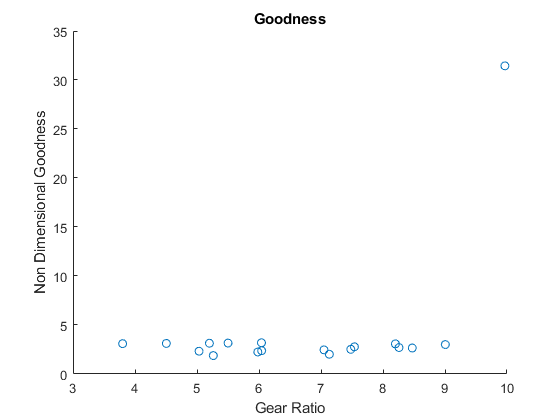

 

%modules = modules(modules ~= excludevals); % removes excluded values from the sweep range

sunTeeths = zeros(size(modules)); % initializes empty vector for calculated minimum sun teeth

% minTeeth is an internal function (defined at the bottom of this file) to
% calculate the minimum number of teeth that will not create an extremely
% thin rim or cause undercutting
for i = 1:1:length(modules)
    effectiveInternalDiameter = 1000*2*sqrt((motor.shaftDiameter / 2 + motor.keyProjHeight)^2 + (motor.keyWidth / 2)^2);
    sunTeeths(i) = minTeeth(20,modules(i),sun,effectiveInternalDiameter); % calculates the minimum number of teeth which avoids both undercut and rim thickness issues
    
end
% Enforces the identical planets constraint in the solution by making the
% minimum number of teeth in the sun gear divisibile by three
%{
if makeIdenticalPlanets
    sunTeeths(mod(sunTeeths,3) == 1) = sunTeeths(mod(sunTeeths,3) == 1) + 2;
    sunTeeths(mod(sunTeeths,3) == 2) = sunTeeths(mod(sunTeeths,3) == 2) + 1;
end
%}
sunPitchDiameters = modules.*sunTeeths; % calculate pitch diameter from module and teeth count

% calculate number of planet teeth required to mesh with the sun for the
% given center distance. Floor is used to get an integer answer
planetTeeths = floor(2 * (target_center_dist - sunPitchDiameters/2)./modules); 

% Calculate actual pitch diameter
planetPitchDiameters = planetTeeths .* modules;     

% Calculate actual center distance (since floor was used it is no longer the target center distance as that would require a fractional tooth)
actual_center_dist = (sunPitchDiameters + planetPitchDiameters)/2; 

% Initialize empty structs and vectors for results
sun_safeties = struct('root',zeros(size(modules)),'flank',zeros(size(modules)));
planet_safeties = struct('root',zeros(size(modules)),'flank',zeros(size(modules)));

sunStages = struct([]);
ringStages = struct([]);
%trial_gb(1).sunStage = [];
%trial_gb(1).ringStage = [];
%trial_gb.ratio =[];

% Create a set of trial solutions for the sun gear set based on applicable
% constraints. 

% For calculation purposes, the two stages of the planet are treated as two
% functionally separate gears fixed on the same shaft.
for i = 1:1:length(modules)
    % Build a trial sun struct which encapsulates important features of the
    % proposed sun gear
    trial_sun = generateGear(modules(i),sunTeeths(i),sun.facewidth,20, 1, 2.25, sun.hardness);

    % Build a trial planet struct which encapsulates important features of the
    % proposed sun stage of the planet gear
    trial_planetSunStage = generateGear(modules(i),planetTeeths(i),planet.sunStage.facewidth*1000,20, 1, 2.25, planet.hardness);

    % Calculate safeties achieved by the meshing gears
    [sun_safety, planetSunStage_safety] = GearStress_PlanetSun(trial_sun,trial_planetSunStage,gearbox,motor,1 , 2.5, 1000);

    % Record safeties to output vector
    sun_safeties.root(i) = sun_safety.root;
    sun_safeties.flank(i) = sun_safety.flank;
    trial_sun.root = sun_safety.root;
    trial_sun.flank = sun_safety.flank;
    trial_planetSunStage.root = planetSunStage_safety.root;
    trial_planetSunStage.flank = planetSunStage_safety.flank;

    planet_safeties.root(i) = planetSunStage_safety.root;
    planet_safeties.flank(i) = planetSunStage_safety.flank;

    sunStages(i).sun = trial_sun;
    sunStages(i).planet = trial_planetSunStage;
end

% Create blank vector for possible number of teeth for given module
planetS2Teeths = zeros(size(modules));


for i = 1:1:length(modules)
    % The gear argument used here is only to pass the gear tooth geometry
    % values (addendum, whole depth factor) not for anything else (number
    % of teeth)
    planetS2Teeths(i) = minTeeth(20,modules(i),planet.ringStage, planetbearingOD);
end

% Calculate the pitch diameter based on the number of teeth for ring stage
% of planets
planetS2pitchDiameters = ones(length(planetS2Teeths)) .* planetS2Teeths' .* modules';

% Calculate the ring pitch diameter based on the ring stage planet pitch
% diameter and the previously calculated center distance
ringPitchDiameters = (planetS2pitchDiameters/2 + actual_center_dist) * 2;

% Calculate the number of teeth required for the ring gear
ringTeeths = ringPitchDiameters ./ modules;

% Force any values that are not whole number teeth to be NaN so they can be
% filtered out easily later
ringTeeths(floor(ringTeeths) ~= ringTeeths) = 0/0;

% Create a square matrix of previously defined modules
modsq = ones(length(modules)) .* modules';

for i = 1:1:length(modules)
    for j = 1:1:length(modules)
        
        % generateGear is an internal function (defined at the bottom of
        % this file) to encapsulate key parameters of the trial solution

        % Build a trial sun struct which encapsulates important features of the
        % proposed sun gear
        trial_ring = generateGear(modsq(i,j),ringTeeths(i,j),ring.facewidth,20, 1, 2.25, ring.hardness);
    
        % Build a trial planet struct which encapsulates important features of the
        % proposed sun stage of the planet gear
        trial_planetRingStage = generateGear(modules(j),planetS2Teeths(j),planet.ringStage.facewidth,20, 1, 2.25, planet.hardness);
    
        ringStages(i,j).ring = trial_ring;
        ringStages(i,j).planet = trial_planetRingStage;

    end
end

% build a vector of gearbox solutions to each
% sun stage/ring stage module combination where the ith index corresponds
% to the sun stage module and the jth index corresponds to the ring stage
% module
counter = 1;
for i = 1:1:length(modules)
    for j = 1:1:length(modules)
        if ~(isnan(ringStages(i,j).ring.teethNum))
            
            trial_gb.sunStageModule(counter) = sunStages(i).sun.module;
            trial_gb.sunStageFacewidth(counter) = sunStages(i).sun.facewidth;
            trial_gb.sunRootSafety(counter) = sunStages(i).sun.root;
            trial_gb.sunFlankSafety(counter) = sunStages(i).sun.flank;
            trial_gb.sunPD(counter) = sunStages(i).sun.pitchDiameter;
            trial_gb.sunTeeth(counter) = sunStages(i).sun.teethNum;
            trial_gb.planetS1RootSafety(counter) = sunStages(i).planet.root;
            trial_gb.planetS1FlankSafety(counter) = sunStages(i).planet.flank;
            trial_gb.planetS1PD(counter) = sunStages(i).planet.pitchDiameter;
            trial_gb.planetS1Teeth(counter) = sunStages(i).planet.teethNum;
            trial_gb.sunStageContactRatio(counter) = getContactRatio(trial_gb.sunStageModule(counter),sunStages(i).sun.pressureAngle,trial_gb.sunTeeth(counter),trial_gb.planetS1Teeth(counter));
            trial_gb.centerDistance(counter) = actual_center_dist(i);

            trial_gb.ringStageModule(counter) = ringStages(i,j).ring.module;
            trial_gb.ringStageFacewidth(counter) = ringStages(i,j).ring.facewidth;
            trial_gb.ringPD(counter) = ringStages(i,j).ring.pitchDiameter;
            trial_gb.ringTeeth(counter) = ringStages(i,j).ring.teethNum;
            trial_gb.planetS2PD(counter) = ringStages(i,j).planet.pitchDiameter;
            trial_gb.planetS2Teeth(counter) = ringStages(i,j).planet.teethNum;
            trial_gb.ringStageContactRatio(counter) = getContactRatio(trial_gb.ringStageModule(counter),ringStages(i).ring.pressureAngle,trial_gb.ringTeeth(counter),trial_gb.planetS2Teeth(counter));

            %trial_gb.ratio(counter) = 1 + trial_gb.sunStage(counter).planet.teethNum * trial_gb.ringStage(counter).ring.teethNum / (trial_gb.sunStage(counter).sun.teethNum * trial_gb.ringStage(counter).planet.teethNum);
            counter = counter + 1;
        end
    end

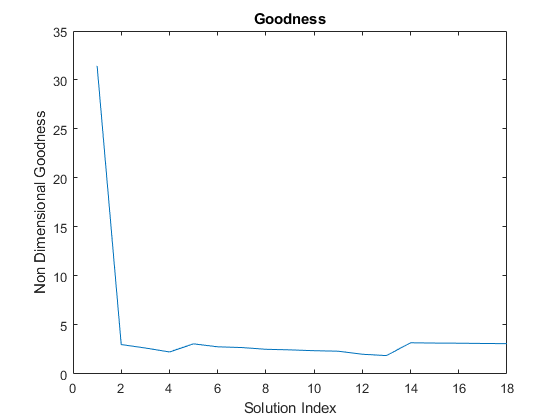

end

% Calculate the achieved gear ratio for all the valid solutions
trial_gb.ratio = 1 + trial_gb.planetS1Teeth .* trial_gb.ringTeeth ./ (trial_gb.sunTeeth .* trial_gb.planetS2Teeth);


% Assign a score to all the solutions that indicate how well they fit the
% constraints. scoreGB is an internally defined function (defined at the
% bottom of the file).
[trial_gb] = scoreGB(trial_gb,target_gr,wear_safety_target,bending_safety_target,gb_rad_lim);

plot(trial_gb.score)
title("Goodness")
ylabel("Non Dimensional Goodness")
xlabel("Solution Index")

plot(trial_gb.ratio)
title("Gear Ratios")
ylabel("Ratio")
xlabel("Solution Index")

table_key = ["Ratio","Score","Sun Stage Module ","Sun Stage Facewidth", "Sun Stage Root Safety","Sun Stage Flank Safety", "Sun Pitch Diameter", "Sun Teeth","Planet S1 Root Safety","Planet S1 Flank Safety","Planet S1 Pitch Diameter","Planet S1 Teeth","Ring Module","Ring Stage Facewidth", "Ring PD","Ring Teeth","Planet S2 PD","Planet S2 Teeth"];
solution_export_data = [trial_gb.ratio' trial_gb.score' trial_gb.sunStageModule' trial_gb.sunStageFacewidth' trial_gb.sunRootSafety' trial_gb.sunFlankSafety' trial_gb.sunPD' trial_gb.sunTeeth' trial_gb.planetS1RootSafety' trial_gb.planetS1FlankSafety' trial_gb.planetS1Teeth' trial_gb.ringStageModule' trial_gb.ringStageFacewidth' trial_gb.ringPD' trial_gb.planetS2PD' trial_gb.planetS2Teeth'];

writematrix(table_key,"Solutions.xlsx")

 
 
 
 
Configuration:

writematrix(solution_export_data,"Solutions.xlsx","Range","A2")

Module (mm): 			0.50

solution_display = false;

--------------------------------------

if solution_display

    [~, index] = max(trial_gb.score);

Sun Gear:

else

--------------------------------------

    index = 3;

Teeth: 			53

end

Pitch Diameter (mm): 	26.50

fprintf(" \n \n \n \nConfiguration:")

fprintf("Module (mm): \t\t\t%.2f",trial_gb.sunStageModule(index))

Sun Stage Planet Gear:

printFormatLine()

--------------------------------------

fprintf(" \n \n")

Teeth: 			99

fprintf("Sun Gear:")

Pitch Diameter (mm): 	49.50

printFormatLine()

fprintf("Teeth: \t\t\t%d",trial_gb.sunTeeth(index))

Ring Stage Planet Gear:

fprintf("Pitch Diameter (mm): \t%.2f",trial_gb.sunPD(index))

--------------------------------------

fprintf(" \n \n \n \n")

Teeth: 			24

fprintf("Sun Stage Planet Gear:")

Pitch Diameter (mm): 	24.00

printFormatLine()

--------------------------------------

fprintf("Teeth: \t\t\t%d",trial_gb.planetS1Teeth(index))

Ratio: 			8.47

fprintf("Pitch Diameter (mm): \t%.2f",trial_gb.planetS1PD(index))
fprintf(" \n \n \n \n")
fprintf("Ring Stage Planet Gear:")
printFormatLine()
fprintf("Teeth: \t\t\t%d",trial_gb.planetS2Teeth(index))
fprintf("Pitch Diameter (mm): \t%.2f",trial_gb.planetS2PD(index))
printFormatLine()
fprintf("Ratio: \t\t\t%.2f",trial_gb.ratio(index))

%{
function [minTeeth, rim_thickness] = minSunTeeth(pressureAngle,module,sun,motor)
    backup_ratio = 1.2;
    deddendum_factor = sun.whole_depth_factor - sun.addendum_factor;
    tooth_height = sun.whole_depth_factor * module;
    rim_thickness = tooth_height * backup_ratio;
    %effectiveInternalDiameter = 2 * sqrt((sun.internalDiameter / 2 + motor.keyProjHeight)^2 + (motor.keyWidth / 2)^2);
    %pitchDiameter = 2 * (rim_thickness + deddendum_factor * module + 1000 * effectiveInternalDiameter / 2);
    pitchDiameter = 2 * (rim_thickness + deddendum_factor * module + 1000 * sun.internalDiameter / 2);
    minTeeth_rim = ceil(pitchDiameter / module);
    minTeeth_undercut = ceil(2 / (sind(pressureAngle))^2);
    minTeeth = max(minTeeth_rim,minTeeth_undercut);
end
%}

function [minTeeth] = minTeeth(pressureAngle,module,gear,internalDiameter)
    % This is the generally accepted value for ratio of rim thickness to tooth height (AGMA standards)
    backup_ratio = 1.2; 
    deddendum_factor = gear.whole_depth_factor - gear.addendum_factor;
    tooth_height = gear.whole_depth_factor * module;
    rim_thickness = tooth_height * backup_ratio;
    pitchDiameter = 2 * (rim_thickness + deddendum_factor * module + internalDiameter / 2);

    % Calculate the minimum number of teeth based on rim thickness
    minTeeth_rim = ceil(pitchDiameter / module);

    % Calculate the minimum number of teeth based on undercutting (lookup
    % formula online)
    minTeeth_undercut = ceil(2 / (sind(pressureAngle))^2);

    % Return the true minimum teeth as the maximum of the two calculated
    % values, as this would meet both requirements
    minTeeth = max(minTeeth_rim,minTeeth_undercut);
end

function [gear] = generateGear(module,teeth,facewidth,pressureAngle, addendum_factor, whole_depth_factor,hardness)
    gear.module = module;
    gear.teethNum = teeth;
    gear.pitchDiameter = module * teeth;
    gear.facewidth = facewidth;
    gear.addendum = addendum_factor * module;
    gear.wholeDepth = whole_depth_factor * module;
    gear.deddendum = gear.wholeDepth - gear.addendum;
    gear.pressureAngle = pressureAngle;
    gear.hardness = hardness;
end

function[] = printFormatLine()
    fprintf("--------------------------------------")
end

function[array] = vectorize(structure,field)
    array = zeros(size(structure));
    for i = 1:1:length(structure)
        array(i) = getfield(structure(i),field);
    end
end
function[array] = nestedVectorize(structure,field,subfield)
    array = zeros(size(structure));
    for i = 1:1:length(structure)
        substruct = getfield(structure(i),field);
        array(i) = getfield(substruct,subfield);
    end
end

function[trial_gb] = scoreGB(trial_gb,target_gr,flank_safety,root_safety, gb_rad_lim)
    % Score is normalized to the target value and then a weight is applied.
    % This prevents targets with numerically high values from over
    % weighting the final score

    % Calculate scores based on gear ratio
    ndRatio = getWeightedScore(10,target_gr,trial_gb.ratio);

    % Calculate scores based on Sun root safety factor
    ndSunRoot = getWeightedScore(2,root_safety,trial_gb.sunRootSafety);

    % Calculate scores based on Sun flank safety factor
    ndSunFlank= getWeightedScore(2,flank_safety,trial_gb.sunFlankSafety);

    % Calculate the bounding radius of the gearbox, this may be the sun
    % stage of the planets or the ring.
    trial_gb.size = max(trial_gb.planetS1PD+trial_gb.sunPD/2 , trial_gb.ringPD/2);

    % sum the individual constraint scores to find the final gearbox score
    trial_gb.score = sum([ndRatio; ndSunRoot; ndSunFlank]);
    
    % get the indices of solutions that exceed the size constraint. More
    % parameters can be added to delete_index if solutions need to be
    % excluded on the basis of more constraints
    delete_index = trial_gb.size > gb_rad_lim;

    % Delete any values matching delete_index from solutions
    %{
    fields =fieldnames(trial_gb);
    for i = 1:numel(fields)
        temp = trial_gb.(fields{i});
        temp(delete_index) = [];
        trial_gb.(fields{i}) = temp;
    end
    %}
    % Zero out the score for any solutions that exceed the size limit
    %trial_gb.score(trial_gb.size > gb_rad_lim) = 0;
    
end

function[score] = getWeightedScore(weight,target,value)
    score = weight * abs(target-value)/target;
    score = 1./score;
end
